# Mohammadreza Arani

## COnvex Optimization Project 2

## 810100511

% Project 2:
% Load Data:

clear; clc; close all;
load ranking_est_data.mat

Now , starting to solve the algorithm:

    We are given the distance relation -------: 

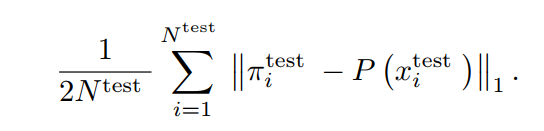

    based on the Predictor [P(x)] ----- we have to find P(x) as to minimize the                   average distance [average test error of the predictor]:

As  a given example we may take P(x) = $\Pi \left(\theta x\right)$

We will consider a simple predictor of the form:

*P*(*x*) = Π(*θx*), where *θ **∈ *$R^{K\times d}$ is the predictor coefcient matrix, and Π : $R^K$ *→ P *is Euclidean projection onto  $\rho$.   

we have to drop using $\Pi$ in the cost-function (Objective) due to non convexity of this function.

As far as I understood, we have to keep track of $\theta$ to make the objective minimum by the means of convex optimization.

After $\theta \;$is achieved, we can use $P\left(x\right)=\Pi \left(\theta x\right)\;$with the achieved $\theta \;$.

% We are given --> X_train , pi_train for 1:N

P=1;

cvx_begin
        variables theta(K,d) ;
        A = double(pi_train) - double(X_train)*theta';
        minimize( sum( sum(abs(A).^P).^(1/P) )  );       
cvx_end

 
Calling SDPT3 4.0: 10200 variables, 5000 equality constraints
------------------------------------------------------------

 num. of constraints = 5000
 dim. of linear var  = 10000
 dim. of free   var  = 200
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|4.1e+01|5.8e+03|5.5e+08| 1.944544e+06| 0:0:00|5.5e+08|1.0e+00|1.0e+00| spchol 1   1
 1|0.000|0.000|4.1e+01|5.8e+03|5.5e+08| 1.944682e+06| 0:0:01|5.5e+08|1.0e+00|1.0e+00| spchol 1   1
 2|0.000|0.000|4.1e+01|5.8e+03|5.5e+08| 1.945393e+06| 0:0:01|5.5e+08|1.0e+00|1.0

N_test = double(N_test);
N = double(N);
% Now determine Average error of train and test data:
Av_Err_for_train_no_Pi = double(pi_train) - double(X_train)*theta'; % With out PI function
Av_Err_for_train_no_Pi_final =  1/(2*N)*sum( sum(abs(Av_Err_for_train_no_Pi).^P).^(1/P) ) 

Av_Err_for_train_no_Pi_final = 4.5895


Av_Err_for_train_with_Pi = double(pi_train) - Pi(double(X_train)*theta'); % With out PI function
Av_Err_for_train_with_Pi_final = 1/(2*N)* sum( sum(abs(Av_Err_for_train_with_Pi).^P).^(1/P) ) 

Av_Err_for_train_with_Pi_final = 2.4880

% Now determine Average error of train and test data:
Av_Err_for_test_no_Pi = double(pi_test) - double(X_test)*theta'; % With out PI function
Av_Err_for_test_no_Pi_final =  1/(2*N_test)*sum( sum(abs(Av_Err_for_test_no_Pi).^P).^(1/P) ) 

Av_Err_for_test_no_Pi_final = 4.7409

% Now determine Average error of train and test data:
Av_Err_for_test_with_Pi = double(pi_test) - Pi(double(X_test)*theta'); % With out PI function
Av_Err_for_test_with_Pi_final =  1/(2*N_test)*sum( sum(abs(Av_Err_for_test_with_Pi).^P).^(1/P) )

Av_Err_for_test_with_Pi_final = 2.6900

This function is given with the data.

%Found theta:
disp(theta+":")

  Columns 1 through 7

    "1.3803:"       "0.36113:"     "0.74898:"     "1.271:"        "0.87337:"     "-0.62152:"    "0.99279:" 
    "-1.4302:"      "0.50151:"     "0.53615:"     "-0.43647:"     "1.0813:"      "-0.89533:"    "0.34893:" 
    "-0.43329:"     "-0.80665:"    "-1.1763:"     "1.2544:"       "-0.76368:"    "-0.31947:"    "-0.52447:"
    "-0.13047:"     "-0.20473:"    "-0.46508:"    "-1.179:"       "-0.26044:"    "-0.31998:"    "-0.80391:"
    "-0.47826:"     "0.66432:"     "0.28675:"     "-0.9765:"      "0.59103:"     "1.3875:"      "1.0985:"  
    "1.3344:"       "-0.67161:"    "-0.55639:"    "0.44077:"      "-0.8717:"     "0.98763:"     "0.083346:"
    "0.50761:"      "-0.62622:"    "0.30685:"     "0.77175:"      "-0.91432:"    "-0.19661:"    "0.045077:"
    "-0.68383:"     "0.45434:"     "0.13937:"     "0.36692:"      "1.3166:"      "0.58641:"     "-0.28504:"
    "-0.064923:"    "1.2589:"      "0.70521:"     "-0.036242:"    "-1.0367:"     "0.51404:"     "-0.36436:"
    "

% theta is 10 * 20
Pi(theta)

ans =     19    10    15    18    16     1    17     3     6     2     8    12    13     9    11     5    14     4     7    20
     1    14    15     5    19     2    12     8    18    13    11     6     4     3     9    10    16    17     7    20
     8     3     1    19     4    12     7    18     2    10     5    13    14     6    15    17    11    16     9    20
    15    14     7     1    13    11     3    16     5    10    18     9    19     8    17     4     2     6    12    20
     3    15     9     1    14    19    18     5     2    12     4    13    10    16    11     8     6    17     7    20
    19     2     4    14     1    15     8     5    17    13    16     9     3    18     7    12    10     6    11    20
    17     3    13    18     1     6    11    19    16     9     2     7     4    15     5    14    10     8    12    20
     6    14    12    13    19    18     8    17     4     2    11    15     7     9    10     5    16     1     3    20
    11    19    18    12  

function r = ranking_est_data(y)
% Returns the rakning of the argument.
% :param y: a 2d array of size N x K or a 1d array of size K, 
% input vector or N vectors to generate the rankings
% :return: a 2d array with ith row being the ranking of the ith row 
% of y if y is a 2d array, and a 1d ranking if y is a 1d array
    if ndims(y) == 1
        [~,r]=sort(y);
        [~,r]=sort(r);
    else
        [~,r]=sort(y, 2);
        [~,r]=sort(r, 2);
    end
end